# **FFT in matlab**

We aim to generate a sine wave in matlab with, for example, a single frequency of 20 Hz. The sine wave amplitude is **a. ** We now determine the sampling rate $f_s$ that should be higher than twice the frequency of signal (Nyquist theorem). You can use phase also for your sine signal as $y=sin(2\pi f t+\phi)$

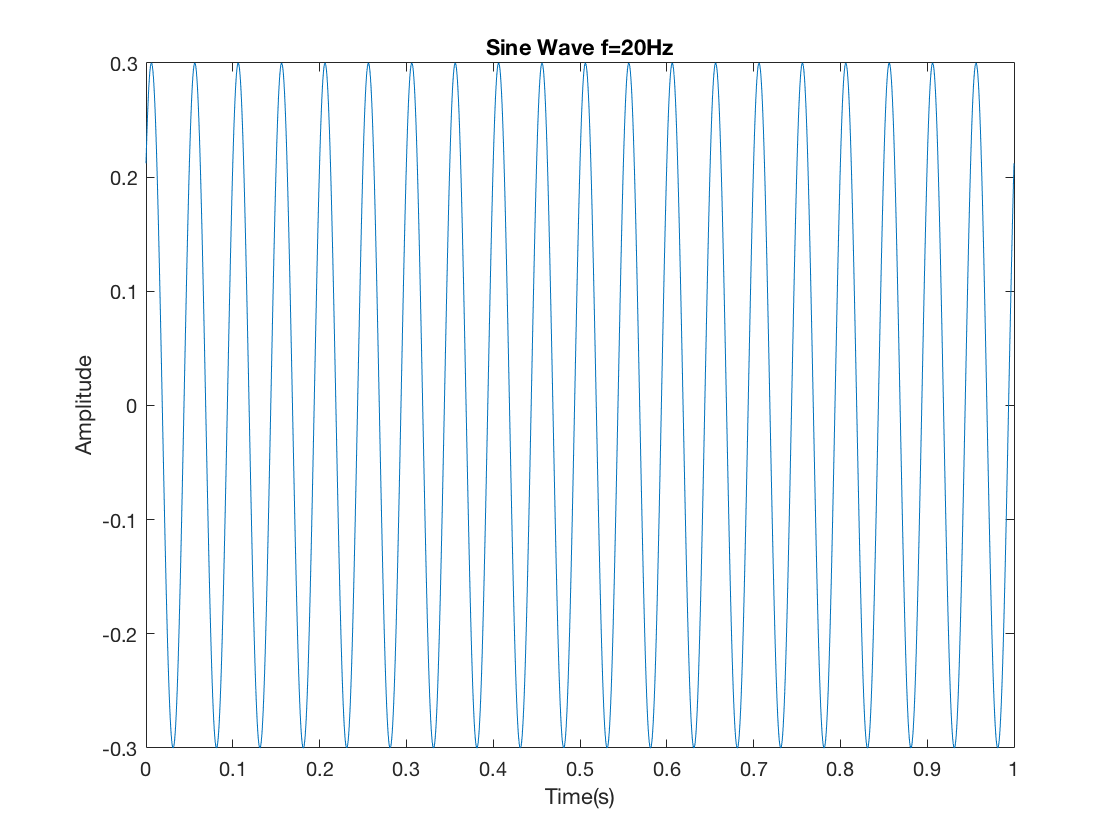

clear all;close all;clc
T=1;
f=20;     % frequency of sine wave
fs=2000;
dt=1/fs; %sampling frequency
phase = pi/4; % phase shift in radians
N=floor(T*fs);
a=0.3;
dt = 1 / fs;

 
t=linspace(0,N*dt,N); %
fs=1/dt;
 
y=a*sin(2*pi*f*t+phase); 
plot(t,y);
title(['Sine Wave f=', num2str(f), 'Hz']);
xlabel('Time(s)');
ylabel('Amplitude');

# **From time domain to frequency domain**

We carry out this transformation using Fast  Fourier Transform (FFT) which is an efficient implementation of Discrete Fourier Transform  (DFT). Typically, the number of points  is taken as power of 2 in the FFT computations.The DFT values are complex and we can plot then its amplitude to identify the frequency of our generated sine wave.

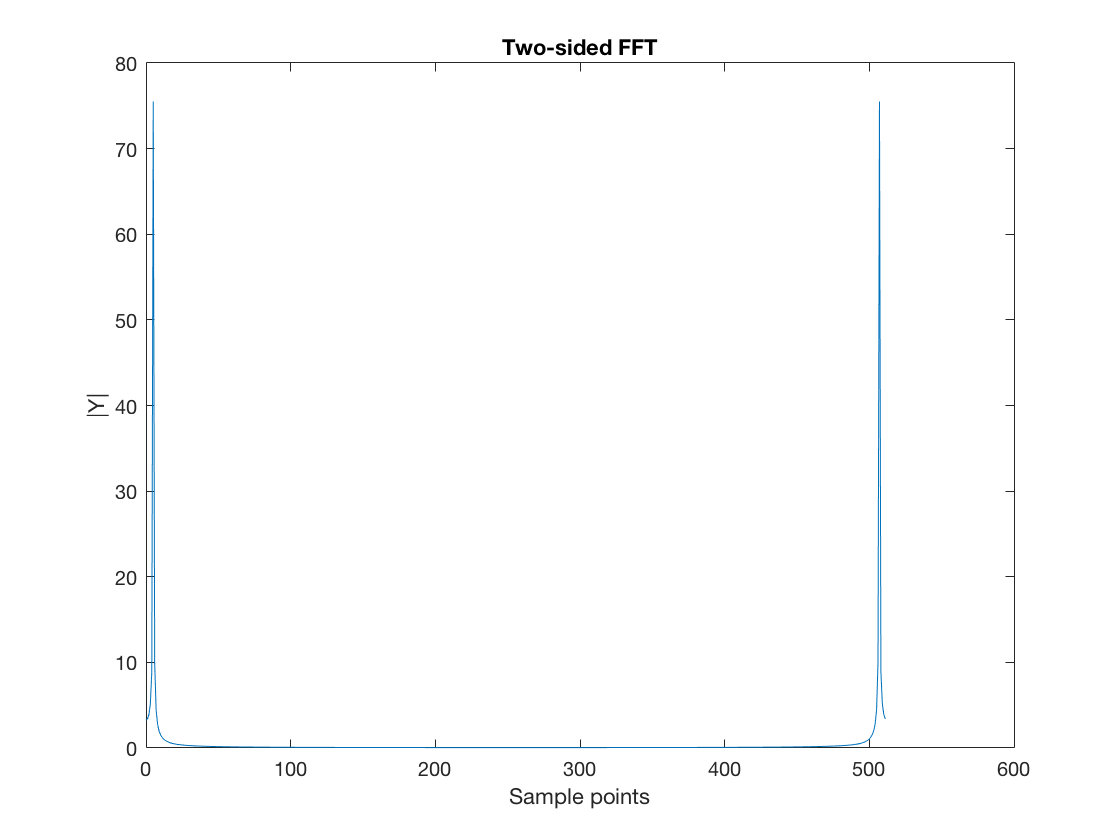

nfft=512; % number of points in DFT
Y=fft(y,nfft); % compute complex DFT using FFT
xvalues=0:nfft-1; % DFT sampling points
plot(xvalues,abs(Y));
title('Two-sided FFT');
xlabel('Sample points')
ylabel('|Y|');

We now focus on the accurate representations of x- and y-axis here. In order to extract the location of sine wave frequency on the x-axis we conduct a normalization over sampling points. First normalize the sampling points to unity: 


$$xvalues\leftarrow xvalues/nfft$$


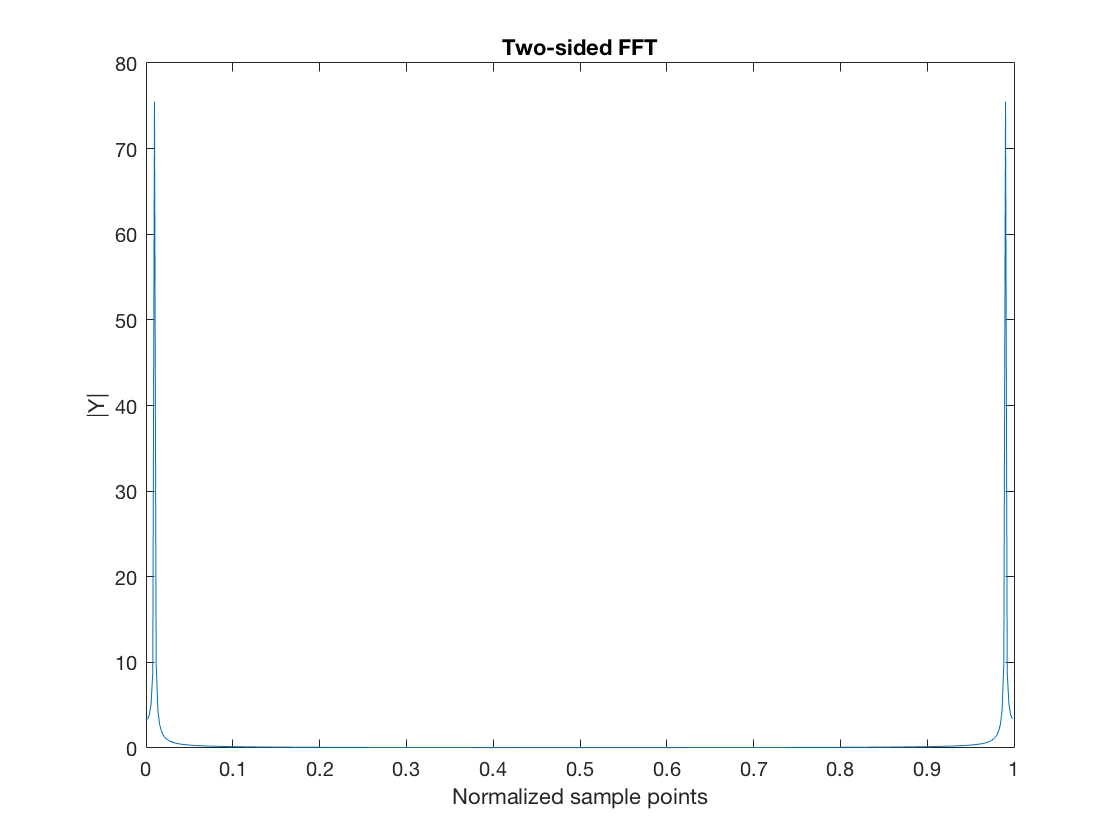

nfft=512; % number of points in DFT
Y=fft(y,nfft); % compute complex DFT using FFT
xvalues=(0:nfft-1)/nfft; % DFT normalized sampling points
plot(xvalues,abs(Y));
title('Two-sided FFT');
xlabel('Normalized sample points')
ylabel('|Y|');

The side lobes are due to spectral leakage.

As you observe, the values on x-axis are all positive and not representing the correct frequency on both positive  and negative frequency axes. We will center DFT values at the middle of x-axis by MATLAB $fftshift$


$$xvalues \leftarrow (-nfft/2:nfft/2-1)/nfft$$
 

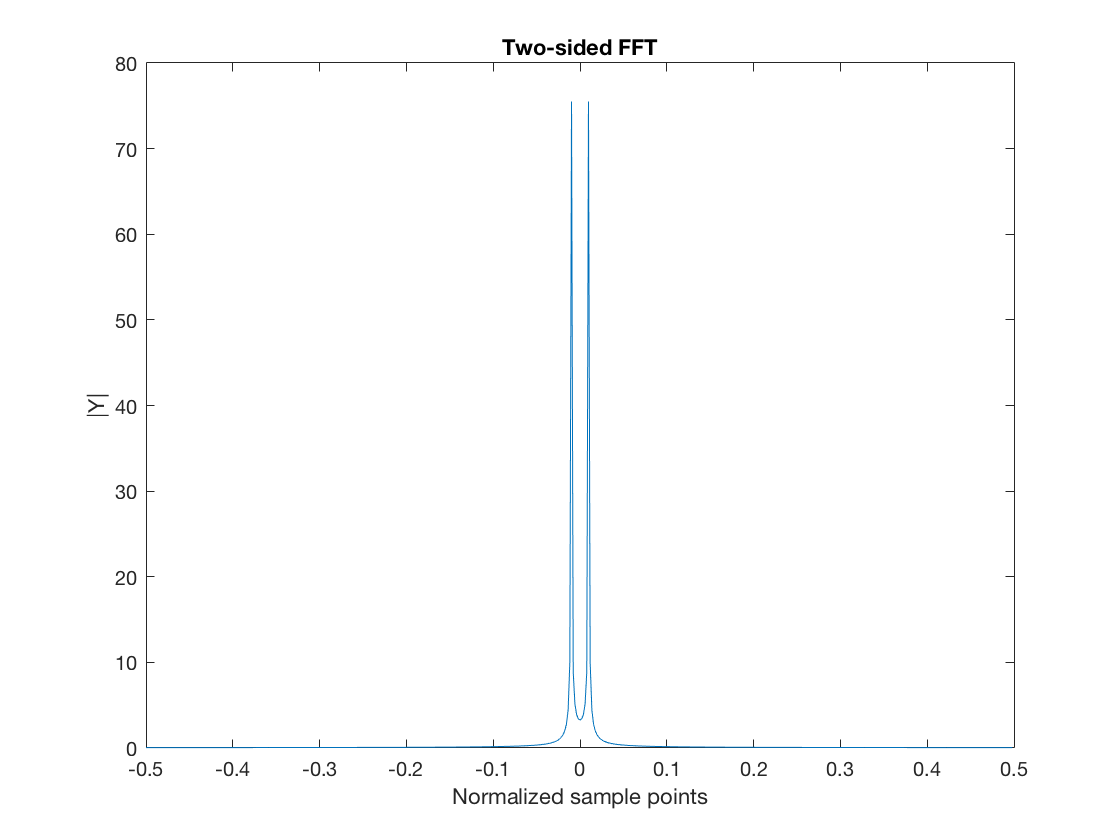

nfft=512; % number of points in DFT
Y=fftshift(fft(y,nfft)); % compute complex DFT using FFT
xvalues=(-nfft/2:nfft/2-1)/nfft; % DFT normalized sampling points
plot(xvalues,abs(Y));
title('Two-sided FFT');
xlabel('Normalized sample points')
ylabel('|Y|');

Still x-axis does not represent frequency in Hz. We can convert xvalues to frequency in Hz by


$$freq=f_s(-nfft/2:nfft/2-1)/nfft$$


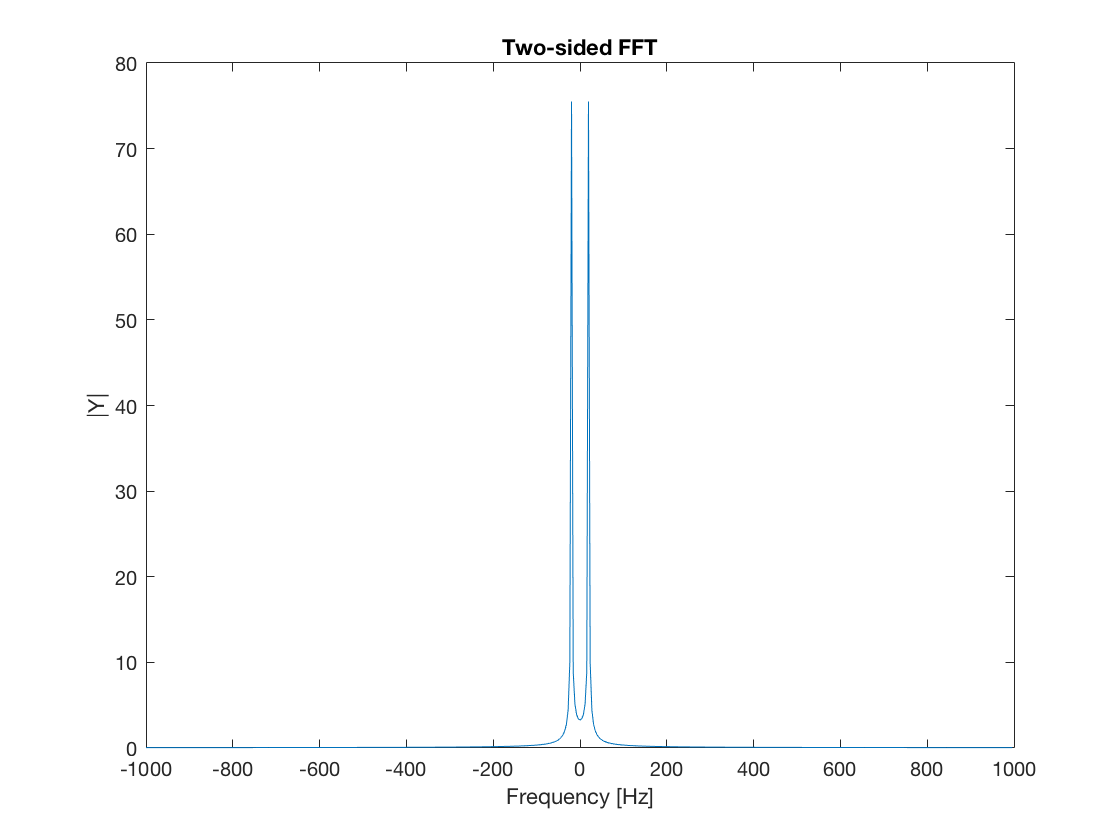

nfft=512; % number of points in DFT
Y=fftshift(fft(y,nfft)); % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; %Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');

Vertical axis does not show the correct amplitude of signal which is $0.3$. To get it correct, we scale the vertical axis by proper scaling factor ( $1/nfft$) as


$$Y\leftarrow Y/nfft$$


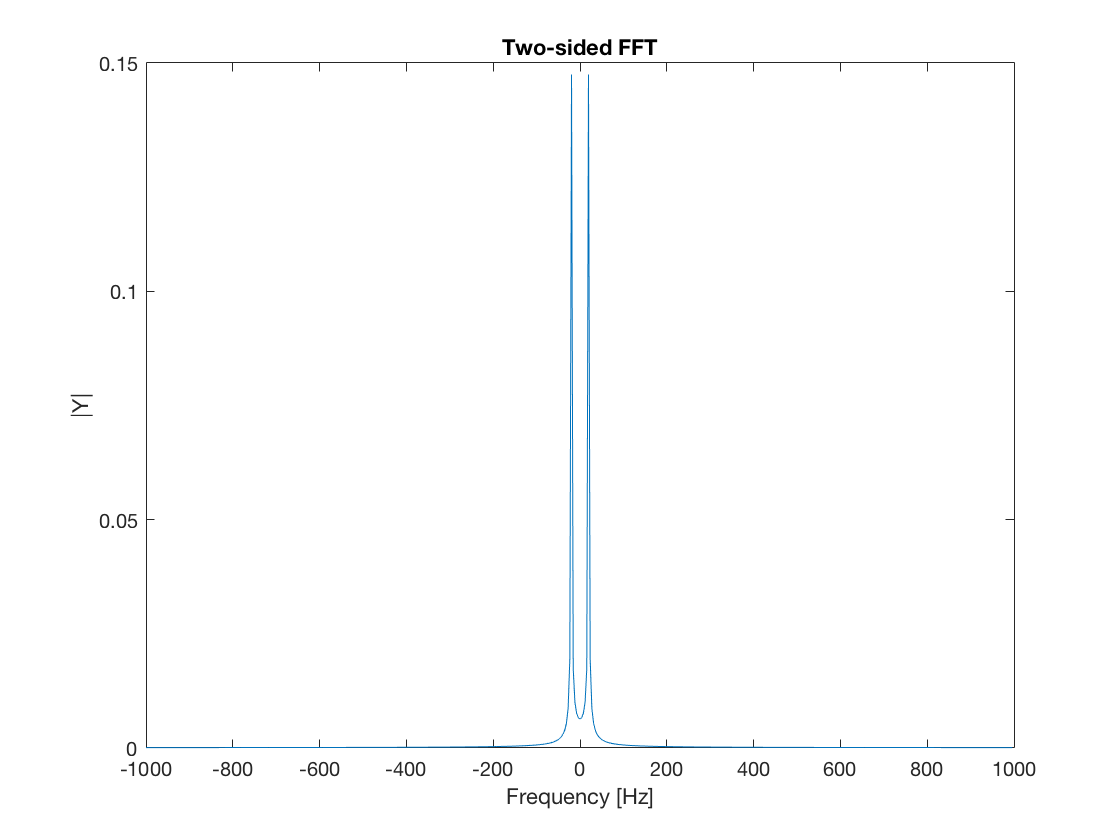

nfft=512; % number of points in DFT
Y=fftshift(fft(y,nfft))/nfft; % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; % Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');

If you use scaling factor of $2/nfft$, you will have 

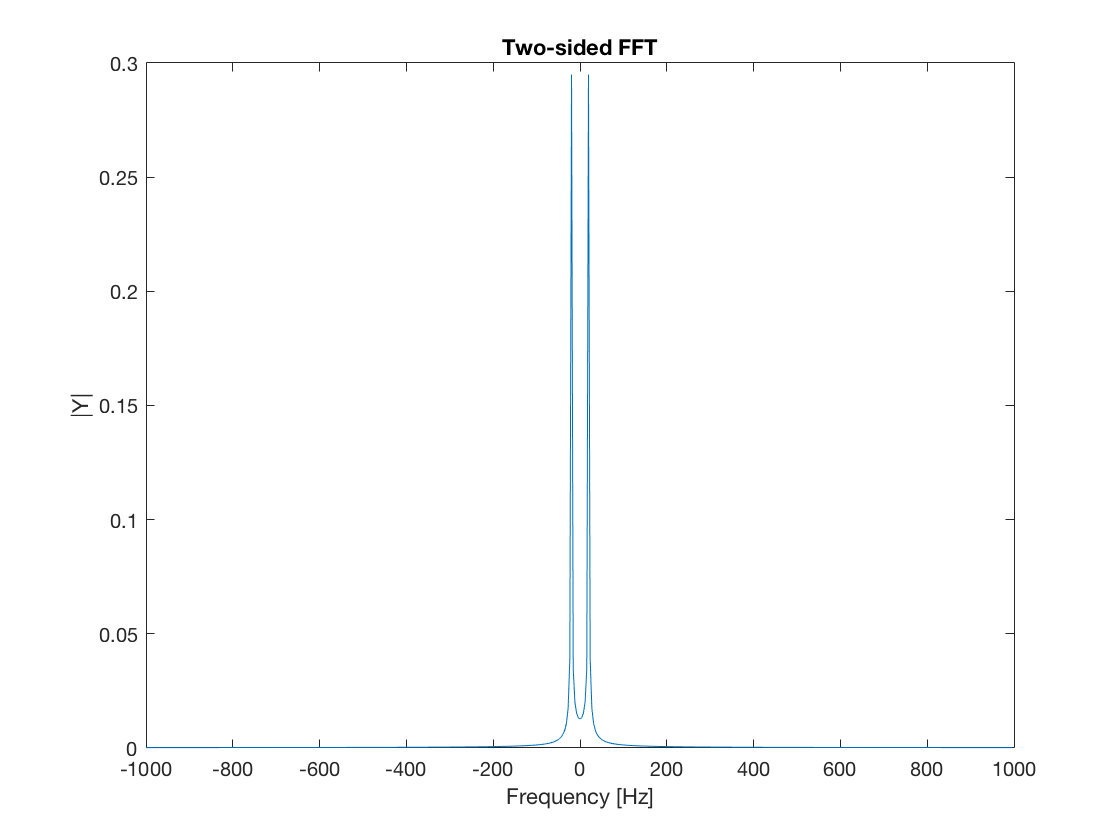

nfft=512; % number of points in DFT
Y=2*fftshift(fft(y,nfft))/nfft; % compute complex DFT using FFT
freq=fs*(-nfft/2:nfft/2-1)/nfft; % Frequency [Hz]
plot(freq,abs(Y));
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');

# Check sampling frequency (Nyquist frequency)

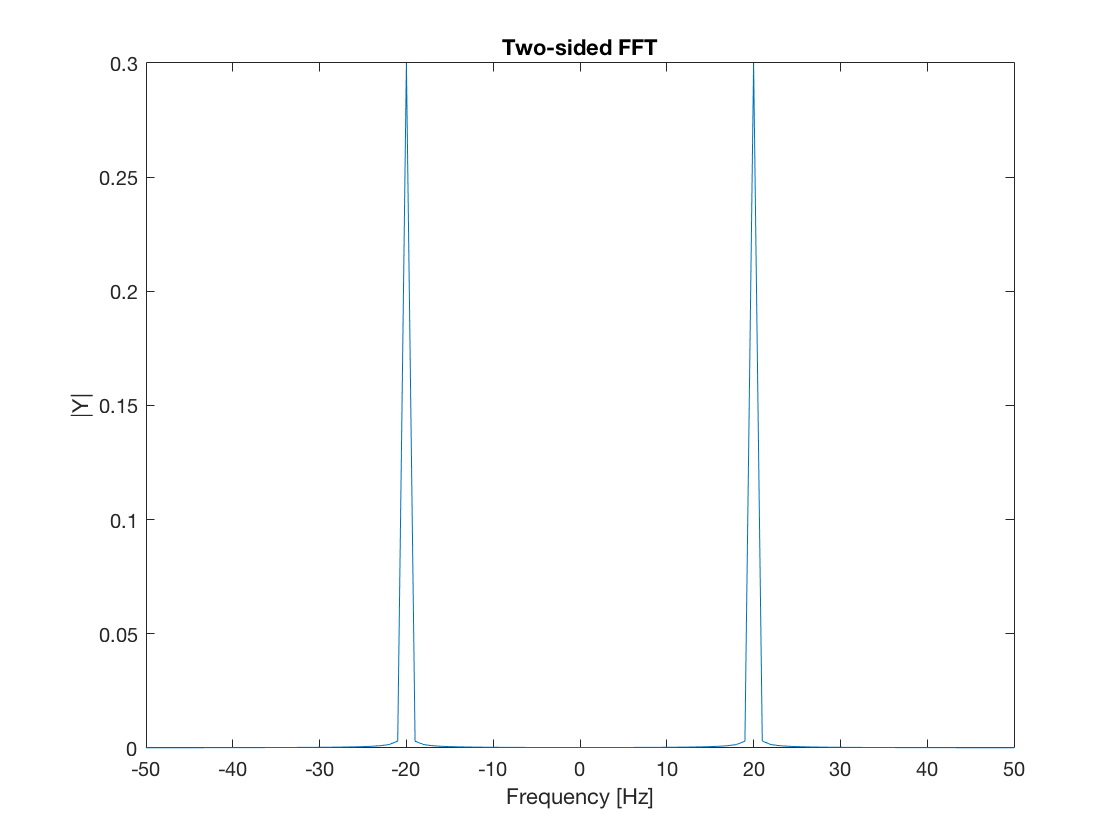

T=1;
f=20;     % frequency of sine wave
fs=2000;
dt=1/fs; %sampling frequency
phase = pi/4; % phase shift in radians
N=floor(T*fs);
a=0.3;
dt = 1 / fs;

 
t=linspace(0,T,N); 
freq=fs*(-N/2:N/2-1)/N; % Frequency [Hz]
y=a*sin(2*pi*f*t+phase); 

Y=fftshift(fft(y)); % compute complex DFT using FFT
plot(freq, 2.0/N * abs(Y))
title('Two-sided FFT');
xlabel('Frequency [Hz]')
ylabel('|Y|');
xlim([-50,50])

Assume our data in time domain has spacing $\delta t$ with length of $T$, the lowest frequency is 1 cycle/$T$and frequency spacing is $1,2,3,\cdots$cycle/$T$ . Highest frequency is $1/(2\delta t)$so that frequencies higher than that cannot be detected. In Fourier expansion:

$y(t_i)=A_1\cos(\omega_1t_i)$, $\omega_1=2\delta \omega$, where $\delta \omega=2\pi df$. Generaglly, in MATLAB $(0,\delta\omega,2\delta\omega,\cdots,(N/2)\delta \omega)$ denote non negative frequencies, and $(-(N/2-1)\delta \omega, \cdots, -2\delta \omega,\delta \omega)$ denote negative frequencies.

In short, frequencies in MATLAB convention are given as follows:


$$(0,\delta\omega,2\delta\omega,\cdots,(N/2)\delta \omega,-(N/2-1)\delta \omega, \cdots, -2\delta \omega,\delta \omega)$$


We have seen how to define these frequencies in MATLAB so far. 

N=512;
T=(N-1)*dt;
x=dt*[0:N-1]';
fmax=1/(2*dt);
df=fmax/(N/2);
f=df*[0:N/2,-N/2+1:-1];
w=2*pi*f;

The FFT amplitude is related to $N$, the number of samples in the FFT. Note that  $N$ to satisfies


$$N=T f_s$$


where dt is the time domain sample spacing.

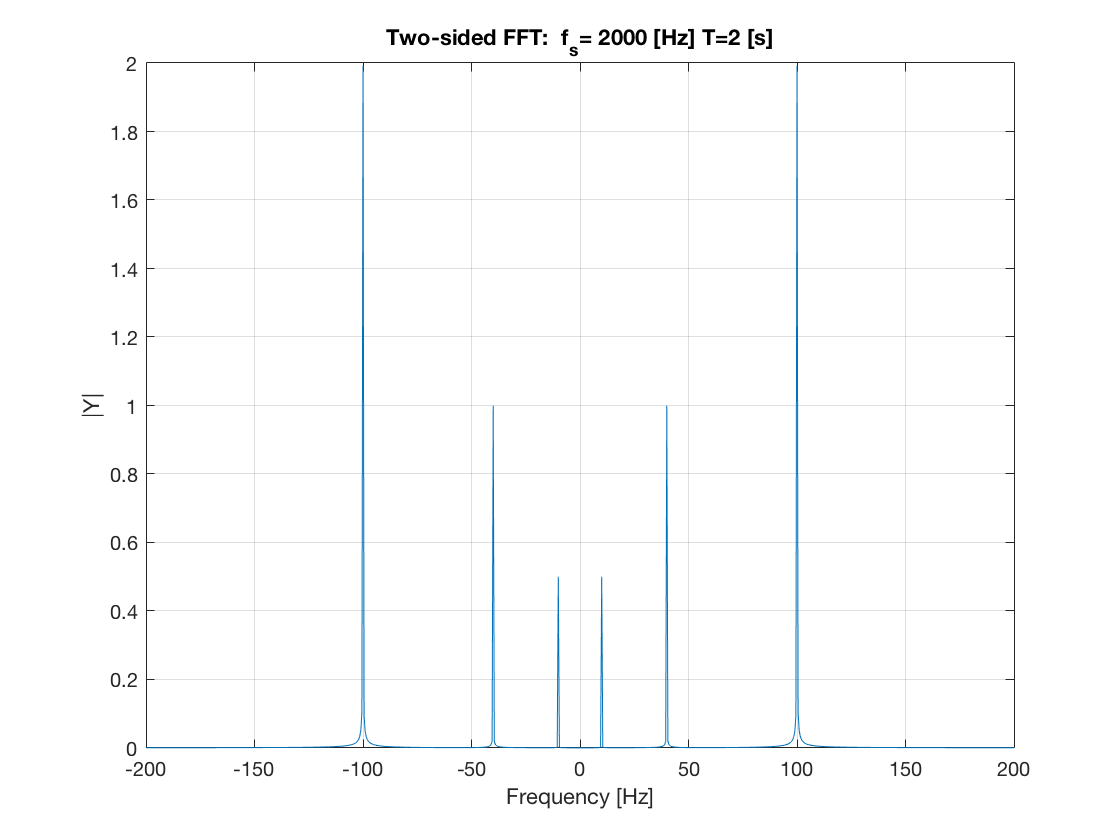


fs=2000;
T=2;
dt = 1 / fs;
N=floor(T*fs);
x = linspace(0.0, T, N);
y = cos(40.0 * 2.0*pi*x) + 0.5*sin(10.0 * 2.0*pi*x)...
    -2*sin(100.0 * 2.0*pi*x);
yf = fftshift(fft(y));
xf = fftshift(fftfreq(N, dt));
magnitude=2.0/N * abs(yf);
plot(xf,magnitude );
title(['Two-sided FFT:  f_s= ' num2str(1/dt) ' [Hz]' ' T=' num2str(N*dt) ' [s]']);
xlabel('Frequency [Hz]')
ylabel('|Y|');

grid on
xlim([-200,200])

[pks,frqs] = findpeaks(magnitude(1:floor(N/2)),'MINPEAKHEIGHT',0.2);
fprintf('%f \n',pks)

1.991554 
0.999467 
0.499817 


# **Fourier series coefficients**

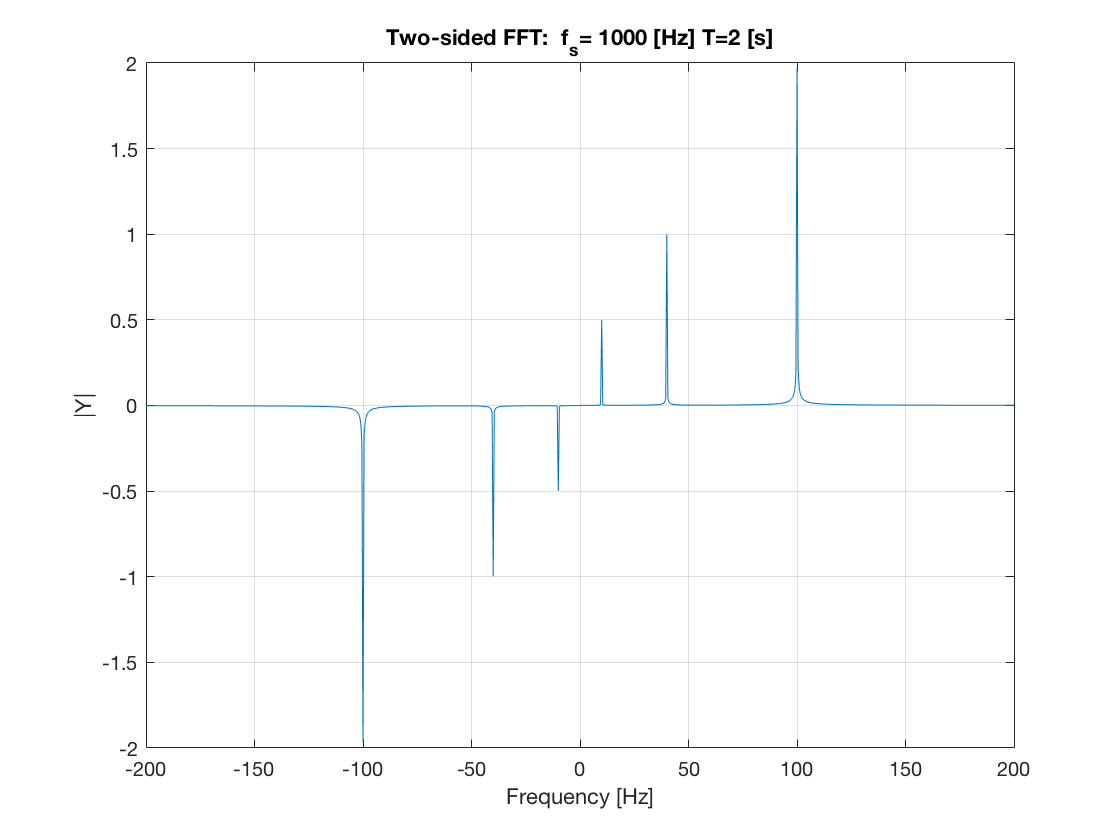

fs=1000;
T=2;
dt = 1 / fs;
N=floor(T*fs);
x = linspace(0.0, T, N);
y = cos(40.0 * 2.0*pi*x) + 0.5*sin(10.0 * 2.0*pi*x)...
    -2*sin(100.0 * 2.0*pi*x);

[freq,magnitude]=calc_fft(y,dt);
plot(freq,magnitude );
title(['Two-si' ...
    'ded FFT:  f_s= ' num2str(1/dt) ' [Hz]' ' T=' num2str(N*dt) ' [s]']);
xlabel('Frequency [Hz]')
ylabel('|Y|');
grid on
xlim([-200,200])